# Autorzy sprawozdania

Piotr Patek, 324 789

Damian Baraniak, 324 851

## Przygotowanie wzorcowych wektorów cech

### Wczytanie nagrania

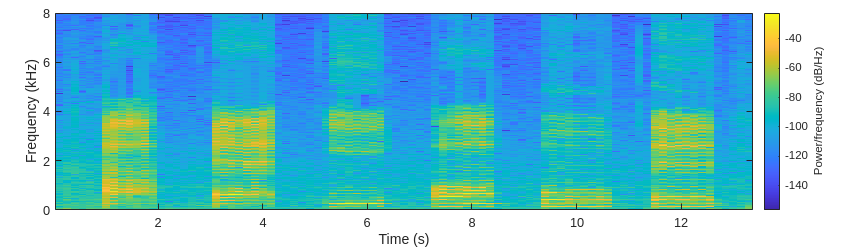

[x, fs] = audioread("recordings/aeiouy_iphone.m4a");
x = resample(x, 16000, fs);
fs = 16000;

win = round(fs * 0.2);
x = x(:, 1);

[s, f, t] = spectrogram(x, win, win / 4, [], fs, 'yaxis');

figure("Position", [0 0 1000 300]);
tiledlayout(1,1,'TileSpacing','Compact','Padding','Compact');
nexttile;
spectrogram(x, win, win/4, [], fs, 'yaxis');

### Etykietowanie danych

W kolejnych kolumnach macierzy znajdują się:

- numer okienka

- numer prążka

- częstotliwość prążka

- numer etykiety

Częstotliwość bazowa dla danego okienka wyznaczana jest przez podzielenie częstotliwości prążka przez jego numer.

sel = [
     8, 11, 1352, 1
     9, 11, 1336, 1
     10, 11, 1334, 1
     11, 11, 1336, 1

    22, 12,  1523, 2
    23, 12,  1512, 2
    24, 12,  1500, 2
    25, 12,  1477, 2

    37,  6,  793, 3
    38,  6,  789, 3
    39,  6,  796, 3
    40,  6,  793, 3

    51, 11,  1504, 4 
    52, 11,  1504, 4
    53, 11,  1496, 4
    54, 11,  1465, 4

    64,  6,  851, 5
    65,  6,  843, 5
    66,  6,  828, 5
    67,  6,  832, 5

    78,  7,  964, 6
    79,  7,  953, 6
    80,  7,  960, 6
    81,  7,  968, 6
];

% sel = [
%      6, 11, 1219, 1
%      7, 11, 1200, 1
%      8, 11, 1195, 1
%      9, 11, 1199, 1
% 
%     19, 10,  1094, 2
%     20, 10,  1082, 2
%     21, 10,  1102, 2
%     22, 10,  1117, 2
% 
%     35,  5,  636, 3
%     36,  5,  629, 3
%     37,  5,  632, 3
%     38,  5,  632, 3
% 
%     48, 7,  796, 4 
%     49, 7,  785, 4
%     50, 7,  769, 4
%     51, 7,  761, 4
% 
%     61,  6,  679, 5
%     62,  6,  691, 5
%     63,  6,  695, 5
%     64,  6,  687, 5
% 
%     74,  7,  871, 6
%     75,  7,  867, 6
%     76,  7,  875, 6
%     77,  7,  863, 6
% ];

Dodatkowo określamy same etykiety dla naszych danych:

labels = ['a', 'e', 'i', 'o', 'u', 'y'];

### Wyznaczenie wektorów cech

Prostą cechą dla głosek dźwięcznych jest rozkład energii sygnału w kolejnych harmonicznych częstotliwości bazowej (F0). Znając jej wartość można wyznaczyć położenie harmonicznych i odczytać z transformaty Fouriera ich amplitudę bądź energię.

% liczba harmonicznych do analizy
n_peaks = 35;

% liczba próbek uczących
n_frames = size(sel, 1);

% macierz z wektorami cech: każda kolumna to wektor dla kolejnej próbki
feats = zeros(n_frames, n_peaks);


for row = 1:n_frames
    % wyliczenie częstotliwości bazowej
    f0 = sel(row, 3) / sel(row, 2);
    
    % ekstrakcja ramki ze spektrogramu
    frame_id = sel(row, 1);
    frame = abs(s(:, frame_id));

    % odczyt wartości amplitudy dla kolejnych harmonicznych
    feats(row, :) = interp1(f, frame, (1:n_peaks) * f0);

    % normalizacja amplitud
    feats(row, :) = feats(row, :) / max(feats(row, :));
end

### Wizualizacja

Wektory cech

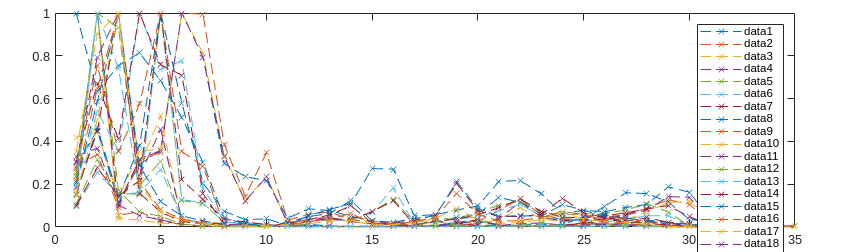

figure("Position", [0 0 1000 300]);
tiledlayout(1,1,'TileSpacing','Compact','Padding','Compact');
nexttile;

plot(feats', 'x--');
legend;

Wzajemne odległości między wektorami - wybór metryki ma znaczenie!

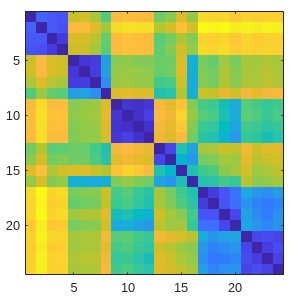

figure("Position", [0 0 300 300]);
tiledlayout(1,1,'TileSpacing','Compact','Padding','Compact');
nexttile;
imagesc(pdist2(feats, feats, 'euclidean'));

## Analiza nagrania

### Wczytanie nagrania

[x, fs] = audioread("recordings/mata1.m4a");
x = resample(x, 16000, fs);
x = x(:, 1);
fs = 16000;

### Segmentacja głosek dźwięcznych w nagraniu

Funkcja geVoicedSegments powinna zwracać macierz, w której każdy wiersz odpowiada znalezionej głosce dźwięcznej, a w kolumnach są po kolei:

- indeks pierwszej próbki 

- indeks ostatniej próbki

- częstotliwość bazowa

s = getVoicedSegments(x, fs)

s = 1.0e+04 *

    0.9621    1.6799    0.0128
    1.7985    2.3140    0.0124
    2.4354    3.3646    0.0119


### Wyznaczenie wektorów cech dla poszczególnych głosek

Algorytm identyczny z użytym do wyznaczenia cech wzorcowych:

- wyznaczenie spektrum sygnału i jego aplitudy

- wybór wartości odpowiadających harmonicznym

- normalizacja wartości

s_count = size(s, 1);

feat = zeros(s_count, n_peaks);
for seg = 1:s_count
    t1 = s(seg, 1);
    t2 = s(seg, 2);
    f0 = s(seg, 3);
    tmp = x(t1:t2);
    [f, A] = getAmp(tmp, fs);
    tmp_f = interp1(f, A, (1:n_peaks) * f0);
    feat(seg, :) = tmp_f / max(tmp_f);
end

### Odległości pomiędzy próbkami z nagrania a wzorcem

% figure("Position", [0 0 1000 200]);
% tiledlayout(1,1,'TileSpacing','Compact','Padding','Compact');
% nexttile;
% imagesc(pdist2(feat, feats, 'cosine'));

### Klasyfikacja próbek

words = {"foki", "czysta", "butelka", "mata"}

words = 1×4 cell array
    {["foki"]}    {["czysta"]}    {["butelka"]}    {["mata"]}


for word_id = 1:length(words)
    for i = 1:4
        path = sprintf("recordings/%s%d.m4a",words{word_id},i)
    [x, fs] = audioread(path);
    x = resample(x, 16000, fs);
    x = x(:, 1);
    fs = 16000;
    s = getVoicedSegments(x, fs);
    
    s_count = size(s, 1);
    
    feat = zeros(s_count, n_peaks);
    for seg = 1:s_count
        t1 = s(seg, 1);
        t2 = s(seg, 2);
        f0 = s(seg, 3);
        tmp = x(t1:t2);
        [f, A] = getAmp(tmp, fs);
        
        tmp_f = interp1(f, A, (1:n_peaks) * f0);
        feat(seg, :) = tmp_f / max(tmp_f);
    end
    
    ret = [];
    
    for seg = 1:s_count
        query = feat(seg, :);
        cls = classify(query, feats, sel(:, 4));
        ret = [ret, labels(cls)];
    end
    ret
    get_word(ret)
    end
end

path = "recordings/foki1.m4a"

ret = 'oi'

ans = "foki"

path = "recordings/foki2.m4a"

ret = 'oi'

ans = "foki"

path = "recordings/foki3.m4a"

ret = 'oi'

ans = "foki"

path = "recordings/foki4.m4a"

ret = 'oi'

ans = "foki"

path = "recordings/czysta1.m4a"

ret = 'yo'

ans = "czysta"

path = "recordings/czysta2.m4a"

ret = 'yo'

ans = "czysta"

path = "recordings/czysta3.m4a"

ret = 'yo'

ans = "czysta"

path = "recordings/czysta4.m4a"

ret = 'yo'

ans = "czysta"

path = "recordings/butelka1.m4a"

ret = 'oa'

ans = "butelka"

path = "recordings/butelka2.m4a"

ret = 'oa'

ans = "butelka"

path = "recordings/butelka3.m4a"

ret = 'oa'

ans = "butelka"

path = "recordings/butelka4.m4a"

ret = 'oa'

ans = "butelka"

path = "recordings/mata1.m4a"

ret = 'iao'

ans = "mata"

path = "recordings/mata2.m4a"

ret = 'iao'

ans = "mata"

path = "recordings/mata3.m4a"

ret = 'iao'

ans = "mata"

path = "recordings/mata4.m4a"

ret = 'ioa'

ans = "Undefined"

% Słowa
% foki - oi
% czysta - yo
% butelka - oa
% mata - iao

## Funkcje do implementacji

function s = getVoicedSegments(x, fs)
% lista segmentów dźwięcznych, opisana kolejno przez:
% - indeks pierwszej próbki
% - indeks ostatniej próbki
% - częstotliwość bazowa

    s = [];
    found_segments = 0;

    win = round(fs * 0.2);
    lbls = zeros(length(x), 1);
    % energia chwilowa
    ste = conv(x.^2, ones(1,win), 'same');
    ste = ste / max(ste);
    
    % wersja z pierwiastkiem
    str = sqrt(ste);
    
    lbls = double(str > 0.07);
    
    x1 = x;
    x2 = [0; x(1:end-1)];
    diff = sign(x1) ~= sign(x2);
    
    zcr = conv(diff, ones(1, win) / win, "same");
    
    found_voiced = false;
    start_voiced = 1;
    end_voiced = 1;

    for i=1:length(lbls)
       if(lbls(i))
            b = zcr(i) > 0.12;
            lbls(i) = lbls(i) + ~b;

            if(lbls(i) == 2 && ~found_voiced)
                start_voiced = i;
                found_voiced = true;
            end
       end

       if(lbls(i) ~= 2 && found_voiced)
            end_voiced = i - 1;
            
            window = x(start_voiced:end_voiced);
            f_max = 300;
            lag_min = fs / f_max;
            [c, lags] = xcorr(window, 'normalized');
            c = c(lags > lag_min);
            lags = lags(lags > lag_min);
            
            if ~isempty(c)
                [pks, loc] = findpeaks(c, "MinPeakProminence", 0.2, "MinPeakWidth", 3);

                if ~isempty(loc)
                    [~, I] = max(pks); 
                    T0 = lags(loc(I)) / fs;
                    f0 = 1 / T0;

                    s(1+found_segments, :) = [start_voiced end_voiced f0];
                    found_segments = found_segments + 1;
                end
           
                
            end
            start_voiced = 1;
            end_voiced = 1;
            found_voiced = false;
       end

  
    end

end

function cls = classify(query, features, ids)
% klasyfikacja pojedynczej próbki
% - query: badany wektor cech Nx1
% - features: wektory treningowe (referencyjne) NxK
% - ids: identyfikatory klasy Nx1

    d = pdist2(query, features, 'euclidean');
    [~, min_id] = min(d, [], 2);
    cls = ids(min_id);
end

function word = get_word(letters)
    word = "Undefined";
    if startsWith(letters,"oi")
        word = "foki";
    elseif startsWith(letters,"yo")
        word = "czysta";
    elseif startsWith(letters,"oa")
        word = "butelka";
    elseif startsWith(letters,"iao")
        word = "mata";
    end
end

## Funkcje pomocnicze

function [f, A] = getAmp(x, fs)
    L = floor(length(x) / 2) * 2;
    Y = fft(x);     % transformata Fouriera

    A = abs(Y);     % amplituda sygnału

    A = A/L;        % normalizacja amplitudy

    A = A(1:L/2+1); % wycięcie istotnej części spektrum
    A(2:end-1) = 2*A(2:end-1);

    f_step = fs/L;     % zmiana częstotliwości
    f = 0:f_step:fs/2; % oś częstotliwości do wykresu
end

function D = distEmd( X, Y )
    % source: http://www.cs.columbia.edu/~mmerler/project/code/pdist2.m

    Xcdf = cumsum(X,2);
    Ycdf = cumsum(Y,2);
    
    m = size(X,1);  n = size(Y,1);
    mOnes = ones(1,m); D = zeros(m,n);
    for i=1:n
      ycdf = Ycdf(i,:);
      ycdfRep = ycdf( mOnes, : );
      D(:,i) = sum(abs(Xcdf - ycdfRep),2);
    end

end